%==========================================================================
% plot_REMpre_vs_interREM_from_csv_LW2min.m
%
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Purpose:
%   Generate scatter plots of REMpre (REM bout duration) versus inter-REM
%   interval (IREM) for rodent datasets (Mouse/Rat; Light/Dark) from per-cycle
%   CSV tables. Each dataset is plotted in its own figure and saved as a PNG.
%
% Axes:
%   - X: IREM (minutes)
%   - Y: REMpre (minutes)
%
% Long-wake (LW) filtering (in-place, per dataset):
%   DROP cycles with Wake >= WAKE_BREAK_MIN minutes using:
%     (1) Preferred: MaxWake* columns (seconds) interpreted as max contiguous
%         Wake block (or closest available proxy, depending on column name).
%     (2) Fallback: Wake column (seconds) interpreted as total Wake.
%     (3) If neither exists: no LW filtering is applied (warning issued).
%
% Inclusion (points plotted):
%   After LW filtering, only rows with finite and positive REMpre and IREM are
%   retained. Durations are converted from seconds to minutes.
%
% Statistics (toolbox-free):
%   - Least-squares line fit: y = a x + b (polyfit)
%   - Pearson correlation r: corrcoef
%   - Approx. two-sided p-value: Fisher z-transform + normal approximation
%
% Inputs:
%   - BigResultTable_mouse_light.csv
%   - BigResultTable_mouse_dark.csv
%   - BigResultTable_rat_light.csv
%   - BigResultTable_rat_dark.csv
%
% Outputs:
%   - One PNG per CSV, saved in the same folder as the CSV, named:
%       <csvBase>_REMpre_vs_interREM_LW<X>min.png
%
% Last updated: 2026-01-16
%==========================================================================


clear; clc;


## Long-wake threshold

WAKE_BREAK_MIN = 2;                 % minutes
WAKE_BREAK_SEC = WAKE_BREAK_MIN*60; % seconds


## Paths

% Mouse
mouseLightCSV = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light.csv";
mouseDarkCSV  = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark.csv";

% Rat
ratLightCSV   = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light.csv";
ratDarkCSV    = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark.csv";


## Define Plot Colors

mouseColor = [0.55 0.27 0.68]; % purple-ish for mouse
ratColor   = [0.90 0.50 0.10]; % orange-ish for rat
fitColor   = [0.00 0.45 0.74]; % MATLAB default blue


## Make the four plots (separate figures)

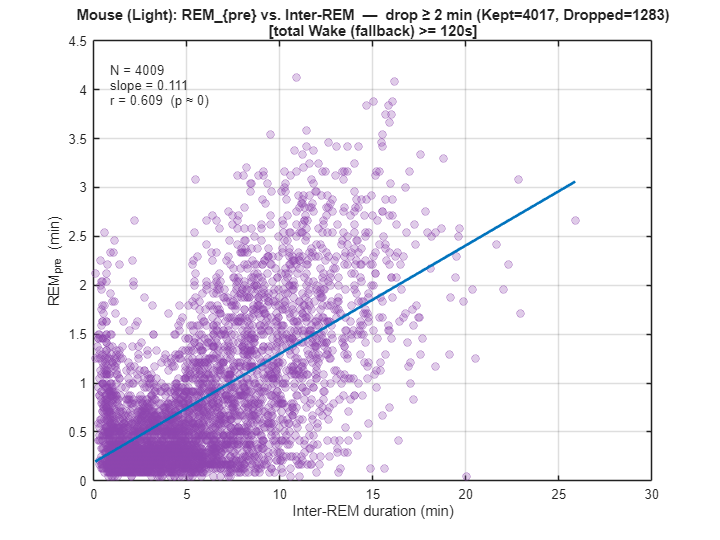

Saved figure: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light_REMpre_vs_interREM_LW2min.png


makeScatterFromCSV(mouseLightCSV, 'Mouse (Light)', mouseColor, fitColor, WAKE_BREAK_SEC, WAKE_BREAK_MIN);

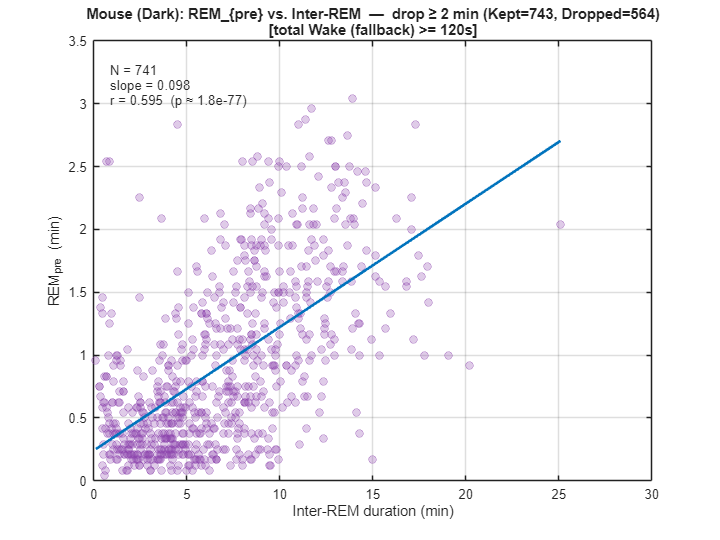

Saved figure: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark_REMpre_vs_interREM_LW2min.png


makeScatterFromCSV(mouseDarkCSV,  'Mouse (Dark)',  mouseColor, fitColor, WAKE_BREAK_SEC, WAKE_BREAK_MIN);

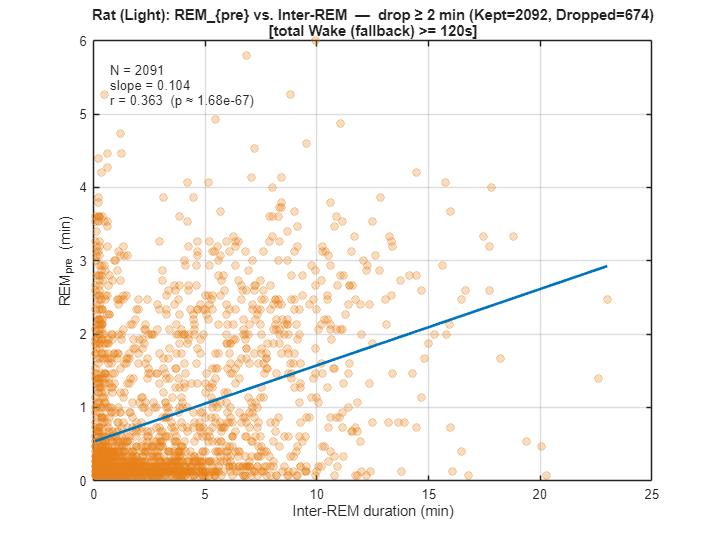

Saved figure: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light_REMpre_vs_interREM_LW2min.png


makeScatterFromCSV(ratLightCSV,   'Rat (Light)',   ratColor,   fitColor, WAKE_BREAK_SEC, WAKE_BREAK_MIN);

makeScatterFromCSV(ratDarkCSV,    'Rat (Dark)',    ratColor,   fitColor, WAKE_BREAK_SEC, WAKE_BREAK_MIN);

Saved figure: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark_REMpre_vs_interREM_LW2min.png


## Function

function makeScatterFromCSV(csvFile, titleStr, pointColor, fitColor, WAKE_BREAK_SEC, WAKE_BREAK_MIN)
% Reads CSV (expects columns REMpre and IREM in seconds), filters long-wake, plots, and saves PNG.
% check file exists -- stop it not
    if ~isfile(csvFile)
        error('File not found: %s', csvFile);
    end

    T = readtable(csvFile, 'TextType','string');


## Apply long-wake filtering

    vn = string(T.Properties.VariableNames);
    maxWakeCandidates = ["MaxWakeSec","MaxWake_s","MaxWakeInIREMSec","MaxWakeInIREM_s","MaxWakeBlockSec","MaxWakeBlock_s"];

    if any(ismember(maxWakeCandidates, vn))
        cname = maxWakeCandidates(find(ismember(maxWakeCandidates, vn), 1, 'first'));
        maxWakeSec = double(T.(cname));
        dropFlag = maxWakeSec >= WAKE_BREAK_SEC;
        filterMsg = sprintf("max Wake block '%s' >= %gs", cname, WAKE_BREAK_SEC);
    elseif ismember("Wake", vn)
        dropFlag = double(T.Wake) >= WAKE_BREAK_SEC;   % fallback proxy
        filterMsg = sprintf("total Wake (fallback) >= %gs", WAKE_BREAK_SEC);
    else
        dropFlag = false(height(T),1);
        filterMsg = "no MaxWake*/Wake — no filtering applied";
        warning('No MaxWake* or Wake column in %s; skipping long-wake filtering.', csvFile);
    end

    T = T(~dropFlag, :);
    kept = height(T);
    dropped = sum(dropFlag);


## Require REMpre & IREM for plotting

    req = {'REMpre','IREM'};
    if ~all(ismember(req, T.Properties.VariableNames))
        error('Required columns %s not found in %s', strjoin(req,', '), csvFile);
    end
% extract Rempre and IREM and convert to minutes
    REMpre_sec = double(T.REMpre);
    IREM_sec   = double(T.IREM);

    ok = isfinite(REMpre_sec) & isfinite(IREM_sec) & (REMpre_sec > 0) & (IREM_sec > 0);
    x_min = IREM_sec(ok)/60;     % Inter-REM duration (min)  -> X
    y_min = REMpre_sec(ok)/60;   % REMpre (min)              -> Y
    n = numel(x_min);

    if n < 2
        warning('Not enough valid rows after filtering for %s in %s (Kept=%d, Dropped=%d).', ...
                titleStr, csvFile, kept, dropped);
        return;
    end


## Fit y = a*x + b (least squares)

    p = polyfit(x_min, y_min, 1);
    a = p(1); b = p(2);

    % ---- Pearson r via corrcoef----
    C = corrcoef(x_min, y_min);
    R = C(1,2);

    % ---- Two-sided p-value via Fisher z ----
    if n >= 4 && abs(R) < 1
        z = atanh(R) * sqrt(n - 3);
        Pval = erfc(abs(z)/sqrt(2));   % two-tailed
    else
        Pval = NaN;
    end


## Plot

    f = figure('Color','w', 'Name', titleStr, 'Position', [100 100 720 540]);
    ax = axes('Parent', f); hold(ax, 'on');

    % Points
    scatter(ax, x_min, y_min, 32, 'o', ...
        'MarkerEdgeColor', pointColor, 'MarkerFaceColor', pointColor, ...
        'MarkerFaceAlpha', 0.28, 'MarkerEdgeAlpha', 0.65);

    % Fit line
    xfit = linspace(min(x_min), max(x_min), 200);
    yfit = polyval(p, xfit);
    plot(ax, xfit, yfit, '-', 'LineWidth', 2.0, 'Color', fitColor);

    % Labels & cosmetics
    xlabel(ax, 'Inter-REM duration (min)');   % X label (IREM)
    ylabel(ax, 'REM_{pre} (min)');            % Y label (REMpre)
    title(ax, sprintf('%s: REM_{pre} vs. Inter-REM  —  drop ≥ %g min (Kept=%d, Dropped=%d)\n[%s]', ...
                      titleStr, WAKE_BREAK_MIN, kept, dropped, filterMsg), ...
          'Interpreter','none');
    grid(ax, 'on'); box(ax, 'on');

    % Stats text in the plot 
    txt = sprintf('N = %d\nslope = %.3f\nr = %.3f  (p ≈ %.3g)', n, a, R, Pval);
    xlim_curr = xlim(ax); ylim_curr = ylim(ax);
    x_text = xlim_curr(1) + 0.03*(xlim_curr(2)-xlim_curr(1));
    y_text = ylim_curr(2) - 0.05*(ylim_curr(2)-ylim_curr(1));
    text(ax, x_text, y_text, txt, 'VerticalAlignment','top', 'FontSize', 10, 'Color', [0.15 0.15 0.15]);

    % Save PNG next to CSV (tag with threshold)
    [pdir, base] = fileparts(csvFile);
    pngName = fullfile(pdir, sprintf('%s_REMpre_vs_interREM_LW%gmin.png', base, WAKE_BREAK_MIN));
    exportgraphics(f, pngName, 'Resolution', 200);
    fprintf('Saved figure: %s\n', pngName);
end
